# Estimation in the Frequency Domain (Discrete Spectrum)

## 1. The Periodogram

A [Periodogram](https://en.wikipedia.org/wiki/Periodogram) is used to estimate the spectral frequency of a signal. We want to estimate the parameters of the signal:


$$x\left(n\right)=a_1 e^{\textrm{j2}\pi F_1 n} +a_2 e^{\textrm{j2}\pi F_2 n} +b\left(n\right)$$


where $b\left(n\right)$ is a white gaussian noise. The code below plots the modulus of the estimated vector magnitudes $\hat{a_{\textrm{MC}} } =\left\lbrack \hat{\;a_1 } \hat{a_2 } \right\rbrack$ while minimizing the mean squared error over different pairs of fixed frequencies. In other words, it shows the solutions to the following equation for different pairs of $F_1$ and $F_2$ fixed:


$$\min_{a_1 ,a_2 } {\left\|x\left(n\right)-\sum_{k=1}^2 a_k e^{\textrm{j2}\pi F_k n} \right\|}^2$$


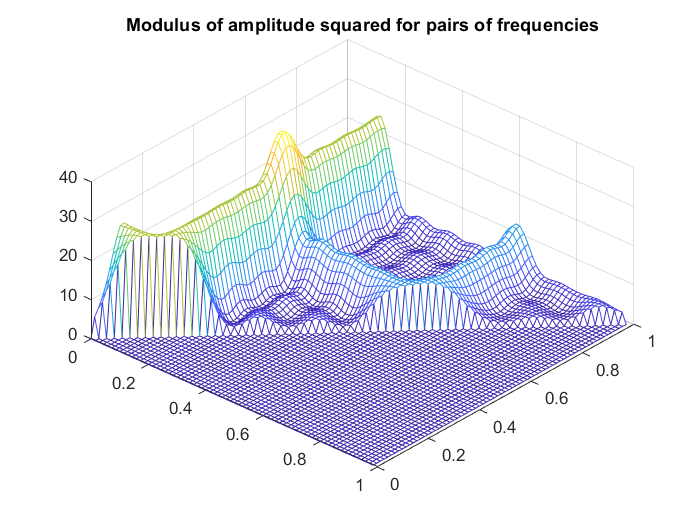

clear all;
a1 = 1.5;   % Want to estiamte
a2 = 1;     % Want to estimate
F1 = 0.12;
F2 = 0.61;
N = 10; temps = (0:N-1)';
s = a1*exp(j*2*pi*F1*temps)+a2*exp(j*2*pi*F2*temps);
SNR = 15; 
P = s'*s/N; 
sigma = sqrt(P)*(10^(-SNR/20));
x = s+sigma*rand(N, 1);

L=70; f=(0:L-1)/L;
M = exp(j*2*pi*temps*f); % matrice a N lignes et L colonnes
K = zeros(L,L);
for i=1:L
    for j=1:i-1
        E = [M(:,i) M(:,j)];
        K(i, j) = abs(x'*E*pinv(E)*x); %pinv Pseudoinverse
    end
end
mesh(f,f,K); title('Modulus of amplitude squared for pairs of frequencies')
view([41.9 50.7])

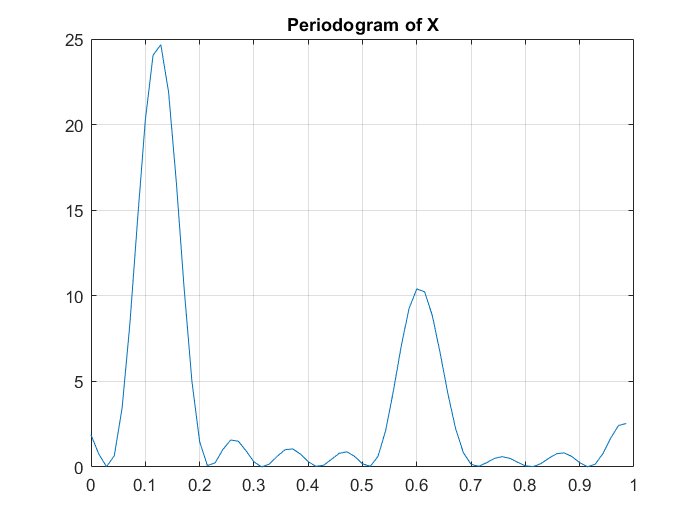

plot(f, abs(fft(x, L)).^2/N); grid; title('Periodogram of X')

It is relatively easy to get the global maximum of the two graphs in MATLAB. The function `max()` is sufficient. To estimate the valeus of $\hat{a} =\left\lbrack \begin{array}{c}
\hat{a_1 } \\
\hat{a_2 } 
\end{array}\right\rbrack$and $\hat{F} =\left\lbrack \begin{array}{c}
\hat{F_1 } \\
\hat{F_2 } 
\end{array}\right\rbrack$using the least squares method shown below:

[a_max_cols,rows_ind] = max(K);
[a_max, col_ind] = max(a_max_cols) ;
l=rows_ind(col_ind);
c=col_ind;
f1_mc = f(c);
f2_mc = f(l);
E_mc = [M(:,c) M(:,l)];
a_mc = abs(pinv(E_mc)*x);
f1_mc, f2_mc, a_mc

f1_mc = 0.1286

f2_mc = 0.6143

a_mc =     1.5614
    0.9958


Using the periodogram to estimate the same:

a_p = [sqrt(23.62*N) sqrt(10.38*N)]/N

a_p =     1.5369    1.0188


We see that the two estimates are very close to each other, since the resolution of the periodogram is good becasue of zero padding.

The minimal duration $N$of a noisy signal of frequency $F$which justifies using a periodogram is given by the Shanon criteria:


$$\frac{1}{N}>2F$$


Below, we give an exmaple to show how this criteria can affect the quality of the solution achieved.

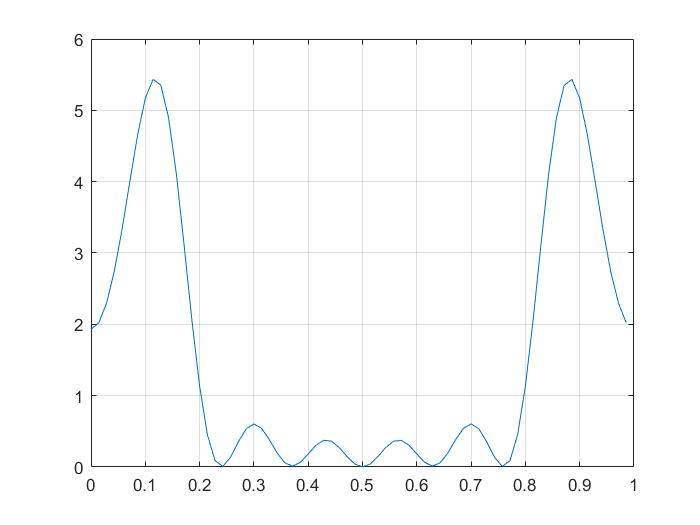

F=0.1; a=2; phi=pi/3;
SNR = 30; P = a^2/2; 
sigma = sqrt(P)*(10^(-SNR/20));
N = 8;
x = a*cos(2*pi*F*(0:N-1)+phi)+sigma*randn(1, N);
figure; plot(f, abs(fft(x, L)).^2/N); grid;

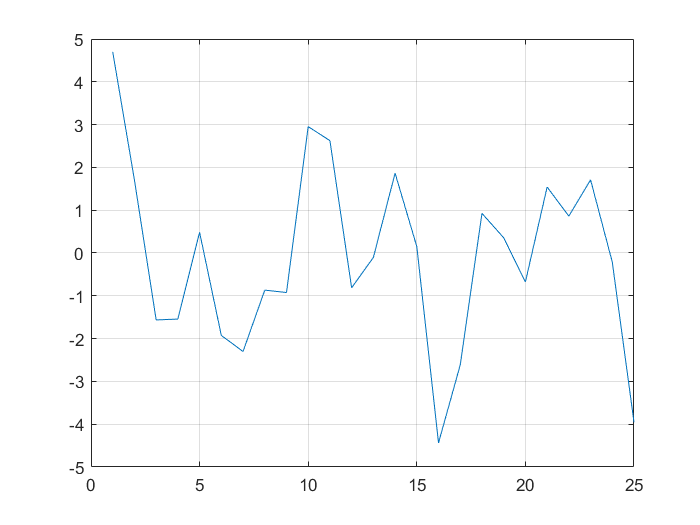

a = [2 1.5 1];
F = [0.1; 0.23; 0.3];
N=25;
s = a*cos(2*pi*F*(0:N-1));
x = s+sqrt(0.5)*randn(1,N);
figure
plot(x); axis([0 N -5 5]); grid

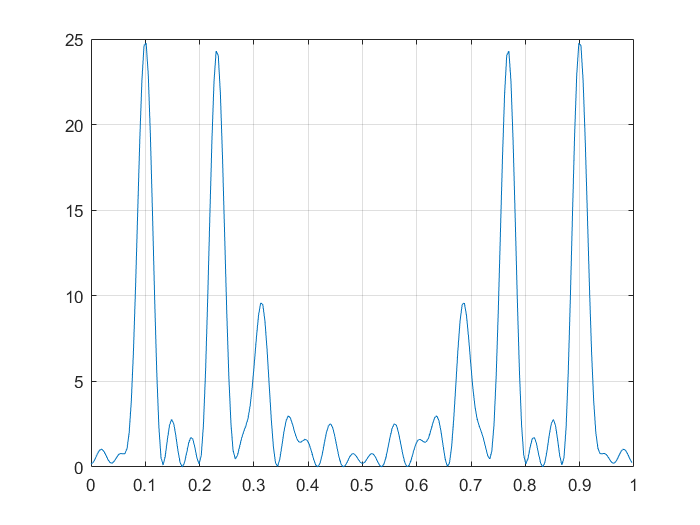

L = 256;
figure; plot((0:L-1)/L, abs(fft(x, L)).^2/N); grid;

save signal x

Below, we load a noisy signal with the harmonics at the frequencies $F=\left\lbrack 0\ldotp 1,\;0\ldotp 23,0\ldotp 3\right\rbrack$. We attempt to recover these frequencies.

load signal.mat
L = 256;
f=(0:L-1)/L;
dF = (0.31-0.23)/2;
periodogramme_temp = abs(fft(x, L)).^2/N;
periodogramme = periodogramme_temp(1:floor(L/2));
P = 3;
pic = zeros(1, P);
indice = zeros(1, P);
frequencies = zeros(1, P);
for i=1:P
    [pic(i), indice(i)] = max(periodogramme);
    periodogramme(indice(i)-L*dF: indice(i)+L*dF)=0;
    frequencies(i) = f(indice(i));
end

frequencies

frequencies =     0.1016    0.2305    0.3125


We see that the frequency estimations are quite accurate.

## MUSIC Algorithm: High Resolution method

The [MUSIC algorithm](https://en.wikipedia.org/wiki/MUSIC_(algorithm)) is used to estimate frequencies which may be very close to each other. Firstly, we will generate a sampling of size $N$of the signal:


$$x\left(n\right)=a_1 \mathrm{cos}\left(2\pi F_1 n\right)+a_2 \mathrm{cos}\left(2\pi F_2 n\right)+b\left(n\right)$$


clear all;
a = [1 2]; F = [0.2; 0.21]; N = 80;
s = a*cos(2*pi*F*(0:N-1));
SNR = 5;
P = s*s'/N;
sigma = sqrt(P)*(10^(-SNR/20));
x = s + sigma*randn(1, N);

If we calculate the DFT without zero-padding, we get the result:

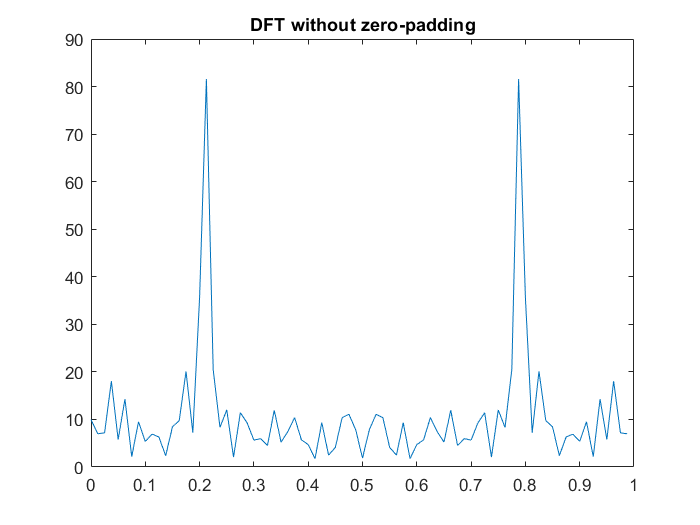

t = (0:N-1)/N;
figure
plot(t, abs(fft(x)))
title('DFT without zero-padding')

We see that it is not possible to distinguish the two frequencies that are very close to each other, at $F_1 =0\ldotp 2$ and $F_2 =0\ldotp 21$.

If we now use the MUSIC algorithm (NOTE: CAN TAKE AROUND 5 MINS TO RUN):

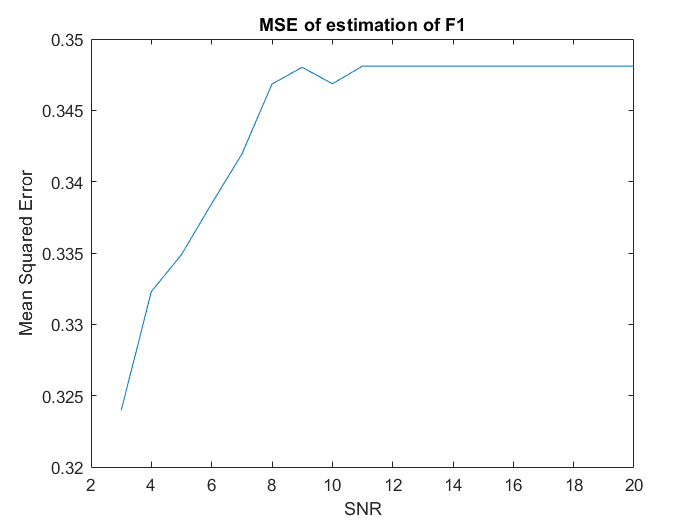

EQM = zeros(18,1);
M = 40; p = 2;
for SNR = 3:20
    for mc = 1:300
        sigma = sqrt(P)*(10^(-SNR/20));
        x = s + sigma*randn(1, N);

        X = zeros(M, N-M);
        for n=1:N-M
            for j=1:M
                X(j, n) = x(n+j);
            end
        end

        R = zeros(M, M);
        for n=1:N-M
            R = R + (X(:,n)*X(:,n)');
        end
        R = R/(N-M);

        [V, D] = eig(R);    %D(1,1) < ... <D(M, M)
        G = V(:, (1:M-p));

        n = 200;
        f = (1:n)/n;
        p_music = zeros(n,1);

        for k=1:n
            a = zeros(M,1);
            for j=1:M
                a(j) = exp(2*i*pi*k/n*(j-1));
            end
            p_music(k) = 1/(a'*(G*G')*a);
        end
        
%         figure
%         plot(f, abs(p_music));
        [Max,Loc] = findpeaks(abs(p_music),'sortstr','descend');
        EQM(SNR-2)=EQM(SNR-2)+((F(1)-Loc(2)/200)^2)/300;
    end
end
figure
plot((3:20), EQM)
title('MSE of estimation of F1')
xlabel('SNR')
ylabel('Mean Squared Error')

We observe that the MSE of the $F_1$ estimate increases with the SNR. It increases till around $\mathrm{SNR}\approx 10$, and then becomes roughly constant.